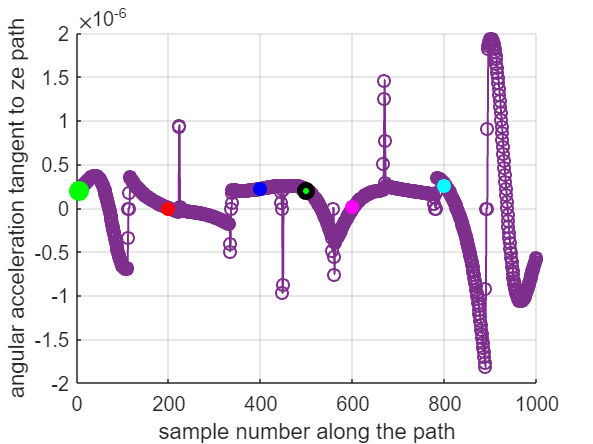

% DEEMED UNNECESSARY
% Tried to see if the derivative of Objective 3 would 
% prove useful. I was wrong. 

% Lake Etsitty, MENG451

C_ = [1:length(avg_change_of_angle) ; avg_change_of_angle];
acc_of_angle = zeros(1,length(C_)-2);

for i = 2:(length(C_)-1)
    x5 = C_(1,(i-1):(i))';
    y5 = C_(2,(i-1):(i))';

    c5 = [[1; 1]  x5]\y5;   

    slope5 = c5(2);
   
    x6 = C_(1,i:i+1)';
    y6 = C_(2,i:i+1)';
    c6 = [[1; 1] x6]\y6;  

    slope6 = c6(2);

    acc_of_angle(1,i-1) = (slope6+slope5)/2;

end

figure
hold all
plot(5:length(acc_of_angle)+4, acc_of_angle,'o-','linewidth',1,'Color',[0.4940, 0.1840, 0.5560])
grid on
xlabel('sample number along the path')
ylabel('double-derivative of the angle change')

title('Derivative of Objective 3')
plot(5,acc_of_angle(1),'o','linewidth',4,"MarkerFaceColor",'g',"MarkerEdgeColor",'g')

plot(pos02,acc_of_angle(1,pos02),'o','linewidth',1,"MarkerFaceColor",'r',"MarkerEdgeColor",'r')
plot(pos04,acc_of_angle(1,pos04),'o','linewidth',1,"MarkerFaceColor",'b',"MarkerEdgeColor",'b')
plot(pos05,acc_of_angle(1,pos05),'o','linewidth',3,"MarkerFaceColor",'g',"MarkerEdgeColor",'k')
plot(pos06,acc_of_angle(1,pos06),'o','linewidth',1,"MarkerFaceColor",'m',"MarkerEdgeColor",'m')
plot(pos08,acc_of_angle(1,pos08),'o','linewidth',1,"MarkerFaceColor",'c',"MarkerEdgeColor",'c')